# RRV application example

## 1. Compute RRV for two scenarios: natural and regulated system

% Natural
sitesDem_ns = readtimetable('ns_sites_demands.xlsx');
sitesSup_ns = readtimetable('ns_sites_supply.xlsx');
rel_sites_ns = reliability(sitesDem_ns.Variables, sitesSup_ns.Variables, 'time').';
res_sites_ns = resilience(sitesDem_ns.Variables, sitesSup_ns.Variables, 'max').';
vul_sites_ns = vulnerability(sitesDem_ns.Variables, sitesSup_ns.Variables, 'maxdef', 'mean').';

% Regulated
sitesDem_rs = readtimetable('rs_sites_demands.xlsx');
sitesSup_rs = readtimetable('rs_sites_supply.xlsx');
rel_sites_rs = reliability(sitesDem_rs.Variables, sitesSup_rs.Variables, 'time').';
res_sites_rs = resilience(sitesDem_rs.Variables, sitesSup_rs.Variables, 'max').';
vul_sites_rs = vulnerability(sitesDem_rs.Variables, sitesSup_rs.Variables, 'maxdef', 'mean').';

## 2. Compute Sustainabilty Index (SI)

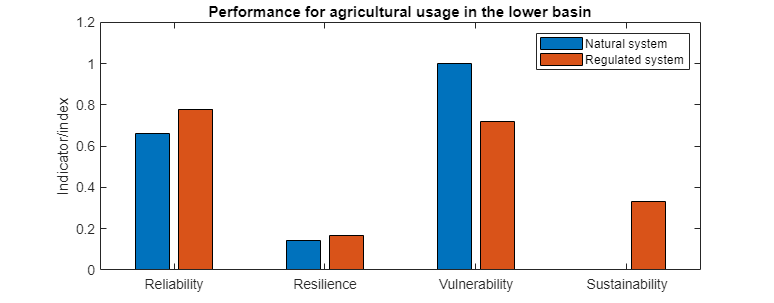

% Normalize vulnerabilty
maxVul = max([vul_sites_ns, vul_sites_rs], [], 2);
maxVul(maxVul == 0) = 1;
vul_sites_ns_norm = vul_sites_ns./maxVul;
vul_sites_rs_norm = vul_sites_rs./maxVul;

% SI
si_sites_ns = (rel_sites_ns.*res_sites_ns.*(1-vul_sites_ns_norm)).^(1/3);
si_sites_rs = (rel_sites_rs.*res_sites_rs.*(1-vul_sites_rs_norm)).^(1/3);

% Group, weighting by annual demands
Sites = readtable('sitesInfo.xlsx');

rel_gp_sites_ns = grouprrv(rel_sites_ns, Sites.dem, Sites.cod);
res_gp_sites_ns = grouprrv(res_sites_ns, Sites.dem, Sites.cod);
vul_gp_sites_ns_norm = grouprrv(vul_sites_ns_norm, Sites.dem, Sites.cod);
vul_gp_sites_ns = grouprrv(vul_sites_ns, Sites.dem, Sites.cod);
si_gp_sites_ns = grouprrv(si_sites_ns, Sites.dem, Sites.cod);

rel_gp_sites_rs = grouprrv(rel_sites_rs, Sites.dem, Sites.cod);
res_gp_sites_rs = grouprrv(res_sites_rs, Sites.dem, Sites.cod);
vul_gp_sites_rs_norm = grouprrv(vul_sites_rs_norm, Sites.dem, Sites.cod);
vul_gp_sites_rs = grouprrv(vul_sites_rs, Sites.dem, Sites.cod);
si_gp_sites_rs = grouprrv(si_sites_rs, Sites.dem, Sites.cod);

% Plot
type = 'agricultural';
basin_location = 'lower';
id = find(strcmp(Sites.type, type) & strcmp(Sites.basin_location, basin_location), 1);
id = Sites.cod(id);

n_rrv = [rel_gp_sites_ns(id); res_gp_sites_ns(id); vul_gp_sites_ns_norm(id); si_gp_sites_ns(id)];
r_rrv = [rel_gp_sites_rs(id); res_gp_sites_rs(id); vul_gp_sites_rs_norm(id); si_gp_sites_rs(id)];
figure('Position', [398.0909 392.8545 751.4182 294.1091])
bar([n_rrv, r_rrv])
xticklabels({'Reliability', 'Resilience', 'Vulnerability', 'Sustainability'})
legend({'Natural system', 'Regulated system'})
title(['Performance for ' type ' usage in the ' basin_location ' basin'])
ylabel('Indicator/index')